Question 1: Part a

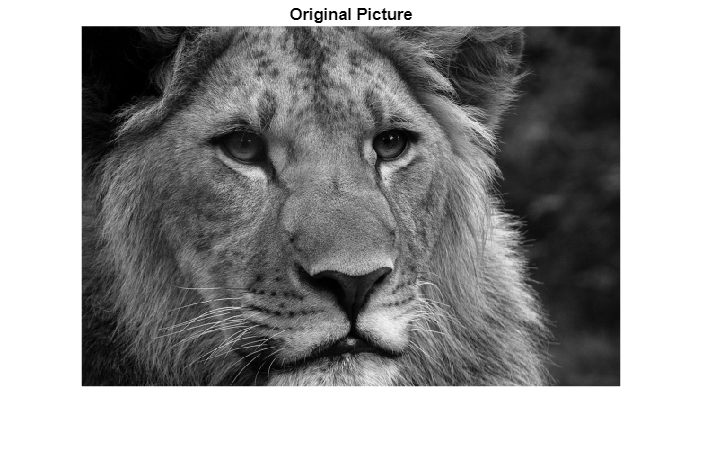

Origin_Image = imread('Lion.png');  
imshow(Origin_Image)
title("Original Picture")

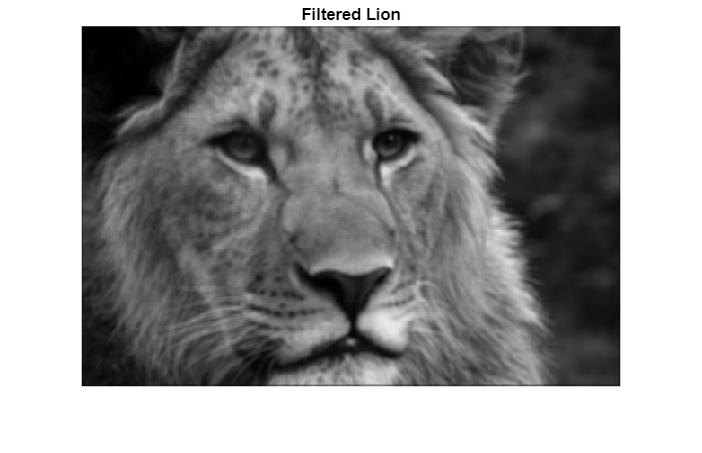

Filter = ones(5,5)/25;
% Setting the filter to be a 5/5 array of ones, then dividing by 25 making
% the weight of each pixel to be 1

Filtered_Image = imfilter(Origin_Image, Filter);
imshow(Filtered_Image)
title("Filtered Lion")

% This is the lion with a filter on it 

%This image is blurier than the initial image due to the averaging of pixels using the 5x5 filter. 

Question 1: Part b

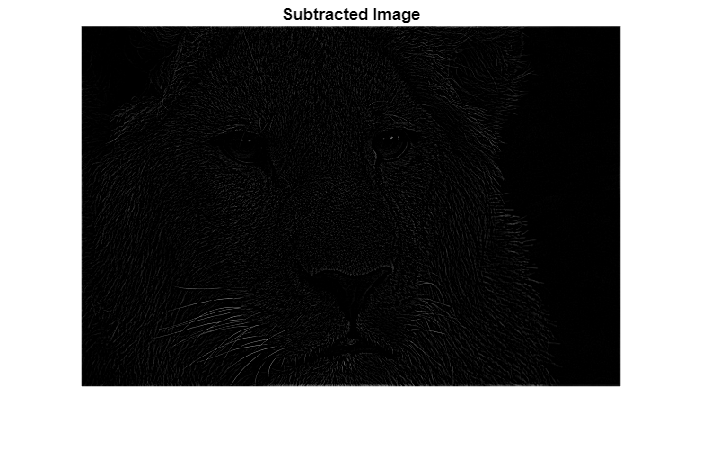

New_Image = Origin_Image - Filtered_Image;
imshow(New_Image)
title("Subtracted Image")

% The resulting image is a darkened version of the details that were
% blurred out of the image after it was filtered. These resemble the edges
% from the original picture which can help with detail or line detection.

Question 1: part c

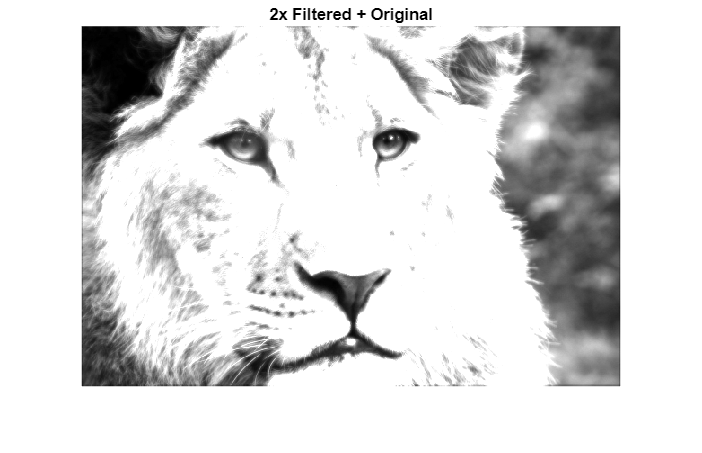

TwoxSubtract = (2 * Filtered_Image);
New_Image = (Origin_Image + TwoxSubtract);
imshow(New_Image)
title("2x Filtered + Original")